clear all;
clc;

% --- 저장된 전처리된 데이터 불러오기 ---
load('DREAMER_preprocessed_filtered_PCA.mat');  % reduced_feature_matrix와 labels_matrix 불러오기

% --- 데이터 준비 ---
X = reduced_feature_matrix;  % PCA로 차원 축소된 특징 벡터
y_valence = labels_matrix(:, 1);  % Valence 라벨
y_arousal = labels_matrix(:, 2);  % Arousal 라벨
y_dominance = labels_matrix(:, 3);  % Dominance 라벨

% --- 데이터 분리 (70% 학습, 30% 테스트) ---
cv = cvpartition(size(X, 1), 'HoldOut', 0.3);  % 70% train, 30% test
trainIdx = training(cv);  % 학습용 데이터 인덱스
testIdx = test(cv);       % 테스트용 데이터 인덱스

% --- 학습 데이터와 테스트 데이터 분리 ---
X_train = X(trainIdx, :);
X_test = X(testIdx, :);
y_train_valence = y_valence(trainIdx, :);
y_test_valence = y_valence(testIdx, :);
y_train_arousal = y_arousal(trainIdx, :);
y_test_arousal = y_arousal(testIdx, :);
y_train_dominance = y_dominance(trainIdx, :);
y_test_dominance = y_dominance(testIdx, :);

% --- SVM 회귀 모델 학습 (Valence) ---
disp('Training SVM model for Valence prediction...');

Training SVM model for Valence prediction...


svm_model_valence = fitrsvm(X_train, y_train_valence, 'KernelFunction', 'linear');

% --- SVM 회귀 모델 학습 (Arousal) ---
disp('Training SVM model for Arousal prediction...');

Training SVM model for Arousal prediction...


svm_model_arousal = fitrsvm(X_train, y_train_arousal, 'KernelFunction', 'linear');

% --- SVM 회귀 모델 학습 (Dominance) ---
disp('Training SVM model for Dominance prediction...');

Training SVM model for Dominance prediction...


svm_model_dominance = fitrsvm(X_train, y_train_dominance, 'KernelFunction', 'linear');

% --- 테스트 데이터에 대한 예측 ---
y_pred_valence = predict(svm_model_valence, X_test);
y_pred_arousal = predict(svm_model_arousal, X_test);
y_pred_dominance = predict(svm_model_dominance, X_test);

% --- 예측 성능 평가 (MSE 계산) ---
mse_valence = mean((y_pred_valence - y_test_valence).^2);
mse_arousal = mean((y_pred_arousal - y_test_arousal).^2);
mse_dominance = mean((y_pred_dominance - y_test_dominance).^2);

% --- 결과 출력 ---
disp(['Mean Squared Error for Valence prediction: ', num2str(mse_valence)]);

Mean Squared Error for Valence prediction: 1.6688


disp(['Mean Squared Error for Arousal prediction: ', num2str(mse_arousal)]);

Mean Squared Error for Arousal prediction: 1.2946


disp(['Mean Squared Error for Dominance prediction: ', num2str(mse_dominance)]);

Mean Squared Error for Dominance prediction: 1.1958


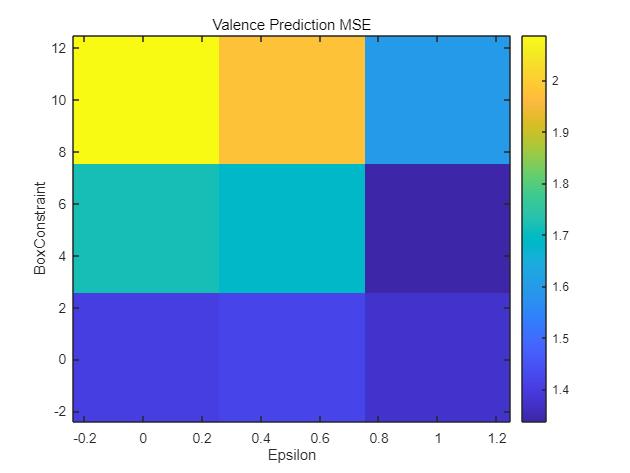

Best BoxConstraint: 1


Best Epsilon: 1


Best MSE: 1.3382


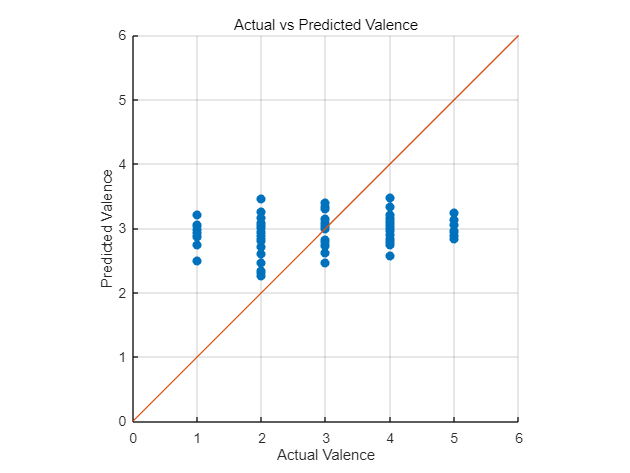

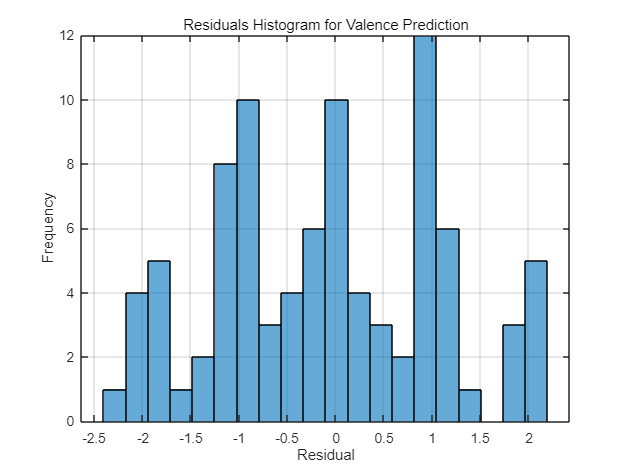

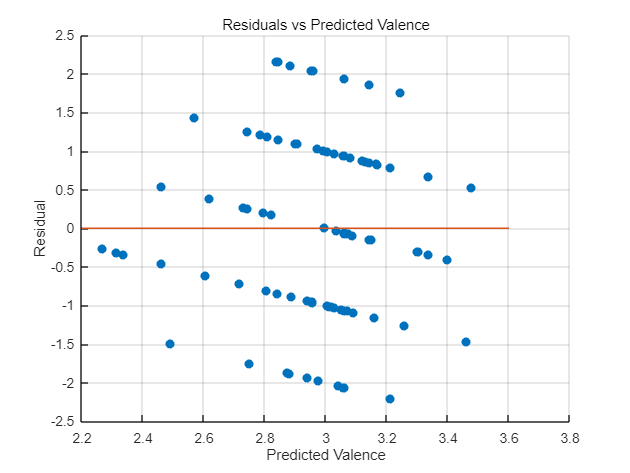

Size of X: 63072


Size of labels_matrix: 303


clear all;
clc;

% --- 저장된 전처리된 데이터 불러오기 ---
load('1017_preprocessed_filtered_PCA.mat');  % reduced_feature_matrix와 labels_matrix 불러오기

% --- 데이터 준비 ---
X = reduced_feature_matrix;  % PCA로 차원 축소된 특징 벡터
y_valence = labels_matrix(:, 1);  % Valence 라벨
y_arousal = labels_matrix(:, 2);  % Arousal 라벨
y_dominance = labels_matrix(:, 3);  % Dominance 라벨

% --- 데이터 분리 (70% 학습, 30% 테스트) ---
cv = cvpartition(size(X, 1), 'HoldOut', 0.3);  % 70% train, 30% test
trainIdx = training(cv);  % 학습용 데이터 인덱스
testIdx = test(cv);       % 테스트용 데이터 인덱스

% --- 학습 데이터와 테스트 데이터 분리 ---
X_train = X(trainIdx, :);
X_test = X(testIdx, :);
y_train_valence = y_valence(trainIdx, :);
y_test_valence = y_valence(testIdx, :);
y_train_arousal = y_arousal(trainIdx, :);
y_test_arousal = y_arousal(testIdx, :);
y_train_dominance = y_dominance(trainIdx, :);
y_test_dominance = y_dominance(testIdx, :);

% --- 하이퍼파라미터 값 설정 ---
box_constraints = [0.1, 1, 10];  % BoxConstraint 값 후보
epsilons = [0.01, 0.1, 1];      % Epsilon 값 후보

% --- 세 가지 감정에 대해 각각 MSE 저장을 위한 배열 초기화 ---
mse_values_valence = zeros(length(box_constraints), length(epsilons));
mse_values_arousal = zeros(length(box_constraints), length(epsilons));
mse_values_dominance = zeros(length(box_constraints), length(epsilons));

% --- 하이퍼파라미터 튜닝 및 MSE 계산 ---
for i = 1:length(box_constraints)
    for j = 1:length(epsilons)
        box = box_constraints(i);
        epsilon = epsilons(j);
        
        % --- SVM 모델 학습 (Valence) ---
        model_valence = fitrsvm(X_train, y_train_valence, 'KernelFunction', 'gaussian', ...
            'BoxConstraint', box, 'Epsilon', epsilon, 'KernelScale', 'auto');
        y_pred_valence = predict(model_valence, X_test);
        mse_values_valence(i, j) = mean((y_pred_valence - y_test_valence).^2);
        
        % --- SVM 모델 학습 (Arousal) ---
        model_arousal = fitrsvm(X_train, y_train_arousal, 'KernelFunction', 'gaussian', ...
            'BoxConstraint', box, 'Epsilon', epsilon, 'KernelScale', 'auto');
        y_pred_arousal = predict(model_arousal, X_test);
        mse_values_arousal(i, j) = mean((y_pred_arousal - y_test_arousal).^2);
        
        % --- SVM 모델 학습 (Dominance) ---
        model_dominance = fitrsvm(X_train, y_train_dominance, 'KernelFunction', 'gaussian', ...
            'BoxConstraint', box, 'Epsilon', epsilon, 'KernelScale', 'auto');
        y_pred_dominance = predict(model_dominance, X_test);
        mse_values_dominance(i, j) = mean((y_pred_dominance - y_test_dominance).^2);
    end
end

% --- Valence MSE 그래프 그리기 ---
figure;
imagesc(epsilons, box_constraints, mse_values_valence);
colorbar;
xlabel('Epsilon');
ylabel('BoxConstraint');
title('Valence Prediction MSE');
set(gca, 'YDir', 'normal');

% --- Arousal MSE 그래프 그리기 ---
figure;
imagesc(epsilons, box_constraints, mse_values_arousal);
colorbar;
xlabel('Epsilon');
ylabel('BoxConstraint');
title('Arousal Prediction MSE');
set(gca, 'YDir', 'normal');

% --- Dominance MSE 그래프 그리기 ---
figure;
imagesc(epsilons, box_constraints, mse_values_dominance);
colorbar;
xlabel('Epsilon');
ylabel('BoxConstraint');
title('Dominance Prediction MSE');
set(gca, 'YDir', 'normal');